clear all
clc
pause(1);


p = 1

p = 1

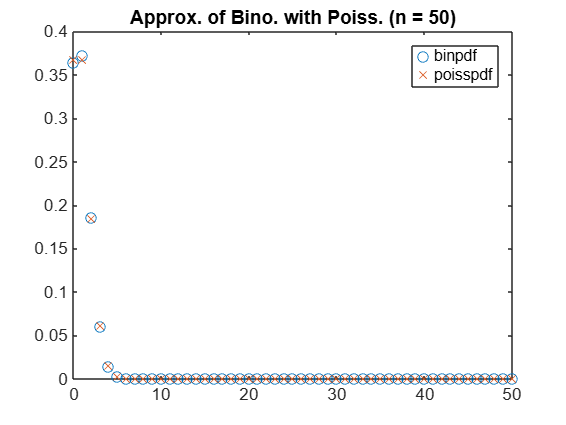

while p > 0.05
    p=input("prob of succes (p <= 0.05)=");
end


for n = 30:50
    k=0:n;
    px=binopdf(k, n, p);
    plot(k, px, 'o');
    hold on;

    lambda = n * p;
    
    poisspx = poisspdf(k, lambda);
    plot(k, poisspx, 'x');
    hold off;

    legend("binpdf", "poisspdf");
    title("Approx. of Bino. with Poiss. (n = "+n+")");

    pause(0.5);
end